# Calculation of Latency and Doppler in a Satellite Scenario

This example shows how to model a LEO satellite constellation, analyze access between the satellites and a ground station, and calculate the latency and the doppler shift between the satellites and the ground station.

## Create a satellite scenario

Create a satellite scenario which will be counting for 3 days.

clear;clc;
sTime = datetime(2025,7,8,0,0,0);
eTime = sTime + minutes(8);
sampleTime = 60;

sc = satelliteScenario(sTime,eTime,sampleTime);

## Add a satellite to the scenario

sat = satellite(sc,"leoSatelliteConstellation.tle");

elements = orbitalElements(sat(1))

elements = struct with fields:
                       MeanMotion: 0.0589
                     Eccentricity: 9.1450e-04
                      Inclination: 55.2591
    RightAscensionOfAscendingNode: 2.0982
              ArgumentOfPeriapsis: 230.1420
                      MeanAnomaly: 118.4821
                           Period: 6.1086e+03
                            Epoch: 04-May-2020 18:45:35
                            BStar: 9.4230e-05


Add a ground station

name = "Madrid Deep space communication complex";
lat = 40.43139;
lon = -4.24806;
gs = groundStation(sc,...
    Name=name,Latitude=lat,Longitude=lon);
ac = access(sat,gs);
% v = satelliteScenarioViewer(sc,ShowDetails=false);
% campos(v, ...
%     29, ...                                        % Latitude in degrees
%     -19, ...                                       % Longitude in degrees
%     7.3e7);                                        % Altitude in meters

## Calculate Latency and Rate of Change of Latency

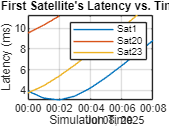

[delay, time] = latency(sat,gs);

plot(time,delay(1,:)*1000);% plot in milliseconds
hold on;
plot(time,delay(20,:)*1000);
plot(time,delay(23,:)*1000);
hold off;
xlim([time(1) time(end)]);
title("First Satellite's Latency vs. Time");
xlabel('Simulation Time');
ylabel('Latency (ms)');
legend('Sat1','Sat20','Sat23');
grid on;

Rate of Change of Latency

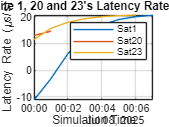

latencyRate = diff(delay,1,2)/sampleTime;
plot(time(1:end-1),latencyRate(1,:)*1e6);% microseconds/seconds
hold on;
plot(time(1:end-1),latencyRate(20,:)*1e6);
plot(time(1:end-1),latencyRate(23,:)*1e6);
hold off;
xlim([time(1) time(end-1)]);
title("Satellite 1, 20 and 23's Latency Rate vs. Time");
xlabel('Simulation Time');
ylabel("Latency Rate (\mus/s)");
legend('Sat1','Sat20','Sat23');
grid on;

## Calculate Doppler Shift and Rate of Change of Doppler Shift

fc = 30e9;
[fshift,time,dopplerInfo] = dopplershift(sat,gs,Frequency=fc);

plot the doppler shift corresponding to the first satellite

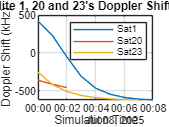

plot(time,fshift(1,:)/1e3); % plot in kHz
hold on;
plot(time,fshift(20,:)/1e3);
plot(time,fshift(23,:)/1e3);
hold off;
legend('Sat1','Sat20','Sat23');
xlim([time(1) time(end)]);
title("Satellite 1, 20 and 23's Doppler Shift vs. Time");
xlabel('Simulation Time');
ylabel("Doppler Shift (kHz)");
grid on;

Doppler rate for the first satellite

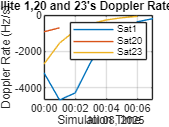

plot(time(1:end-1),dopplerInfo.DopplerRate(1,:))  % Plot in Hz/s
hold on;
plot(time(1:end-1),dopplerInfo.DopplerRate(20,:));
plot(time(1:end-1),dopplerInfo.DopplerRate(23,:));
hold off;
xlim([time(1) time(end-1)])
title("Satellite 1,20 and 23's Doppler Rate vs. Time")
xlabel("Simulation Time")
ylabel("Doppler Rate (Hz/s)")
legend('Sat1','Sat20','Sat23');
grid on

Retrieve ear information

[alt,elevation,slantRange] = aer(sat,gs);

plot doppler per elevation angle

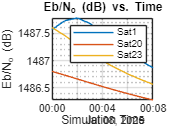

% FSPL of Uplink Signal
% Assume carrier frequency of 30 GHz
% Assume Transmission Power of 20 dB
La = 0.3;
antenna_heta = 0.6;
diameter = 0.5;
Ltx = 0.5;
Pt = 20;
c = 3e8;
k = physconst('boltzman');
FSPL = 20*log10(slantRange) + 20*log10(fc) - 147.55 + La;
Gmax = antenna_heta * (pi*diameter*fc/c)^2;
EIRP_ul = Pt - Ltx + Gmax;
SNR_ul = EIRP_ul - FSPL + 6.9 - 10*log10(k);
Rb = 10; % bps
semilogy(time,SNR_ul(1,:)./Rb);
hold on;
semilogy(time,SNR_ul(20,:)./Rb);
semilogy(time,SNR_ul(23,:)./Rb);
hold off;
legend('Sat1','Sat20','Sat23');
xlim([time(1) time(end)]);
title("Eb/N_o (dB) vs. Time");
xlabel("Simulation Time");
ylabel("Eb/N_o (dB)");
grid on;

Show the name and the orbit of the first satellite and plot its future ground track, or lead time, over 12 hours. Dashed yellow shows the future ground track, and solid yellow shows the past ground track.

% sat(1).ShowLabel = true;
% show(sat(1).Orbit);
% groundTrack(sat(1), ...
%     LeadTime=12*3600);   % In seconds
% campos(v,84,-176,7.3e7);

Play the scenario with the satellites and ground station.

% play(sc)

Bit-error rate

% ebno = SNR_ul(1,:)./Rb;
% berQPSK = 0.5*(2*qfunc(sqrt(2*ebno)) - (qfunc(sqrt(2*ebno))).^2);
% semilogy(time,berQPSK(1,:));
% hold on;
% semilogy(time,berQPSK(20,:));
% semilogy(time,berQPSK(23,:));
% hold off;
% legend('Sat1','Sat20','Sat23');
% xlim([time(1) time(end)]);
% title("BER of QPSK vs. Time");
% xlabel("Simulation Time");
% ylabel("BER");
% grid on;

Can we get the number of times the access is the same for many satellites of the constellation?

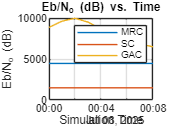

figure;
plot(time,(SNR_ul(1,:)+SNR_ul(20,:)+SNR_ul(23,:))./Rb);
maxSNR = max(SNR_ul(1,:),SNR_ul(20,:));
maxSNR = max(maxSNR,SNR_ul(23,:))./Rb;
%   slant range based selection
maxSlantRange = zeros(1,9);
for i=1:9
    maxSlantRange(i) = findMaxOf3(slantRange(1,i),slantRange(20,i),slantRange(23,i));
end

hold on;
plot(time,maxSNR);
%   slant range based selection
plot(time, maxSlantRange.*(SNR_ul(1,:)./slantRange(1,:)+...
    SNR_ul(20,:)./slantRange(20,:)+SNR_ul(23,:)./slantRange(23,:))...
    ./Rb);
hold off;
legend('MRC','SC','GAC');
xlim([time(1) time(end)]);
title("Eb/N_o (dB) vs. Time");
xlabel("Simulation Time");
ylabel("Eb/N_o (dB)");
grid on;

Save the aer data

writeMatrix2Txt(alt,'alt.txt');
writeMatrix2Txt(elevation,'el.txt');
writeMatrix2Txt(slantRange,'sr.txt');